# 人間の活動のクラスタリング

 これは教師なし学習の例です。 

人間の活動センサー データには、さまざまな活動 (歩く、横になる、座るなど) をしているときに人が装着しているスマートフォンから取得したセンサー測定から得られた観測値が含まれています。 [実験ビデオを見る](https://www.youtube.com/watch?v=XOEN9W05_4A) 。 

この分析の目的は、ラベルがない場合に、類似した活動のクラスターとそれらが表す可能性のあるものを識別することです。 ** この教師なし学習の例では、各観測値がどのタイプの活動に対応するかは事前にわかりません。 **

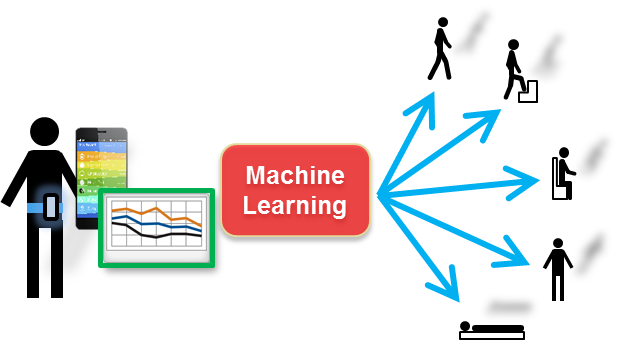

** ハウスキーピング **

ワークスペースをクリアします。 

clear; 

正しいディレクトリにいるかどうかを再確認します。正しい場合は、フォルダーとサブフォルダーをパスに追加します。 

% これを実行して確認します
if isfolder('Additional Files')
    addpath(genpath(pwd))
    disp('You are in the correct directory. Please continue.')
else  
    disp('Please navigate to the proper Directory')
end

## データのロード

6 つの変数 (それぞれが異なるセンサーからの測定値を表す) を含む `rawSensorData` をロードします。 `trainActivity` 変数には、モデルの評価にのみ使用される実際のラベルが含まれています。 

データは、[ホーム] タブにある [データのインポート] ツールを使用してインポートできます。 

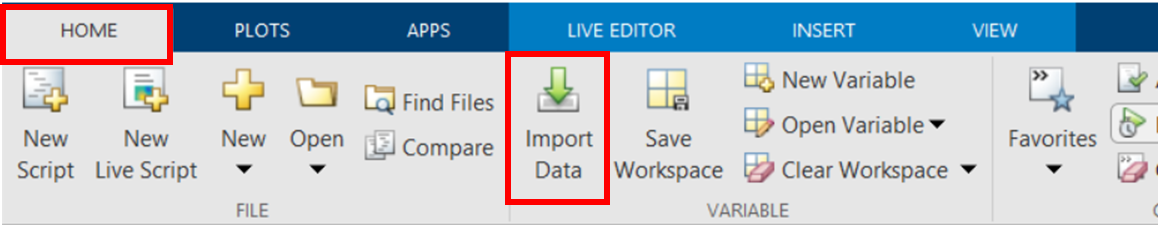

そこで、***Additional Files*** フォルダー (ダブルクリック) と *** rawSensorData_train.mat ファイル ([開く] をクリックするかダブルクリック) を選択します。デフォルトではすべての変数が選択されているので、[完了] を押します。 ***

注: デスクトップ MATLAB® では、下部のボックス (MATLAB コードの生成) をオンにすることで、このアクティビティのコードを生成できます。MATLAB Online では、* コマンド ウィンドウ * にコードが表示されます。 

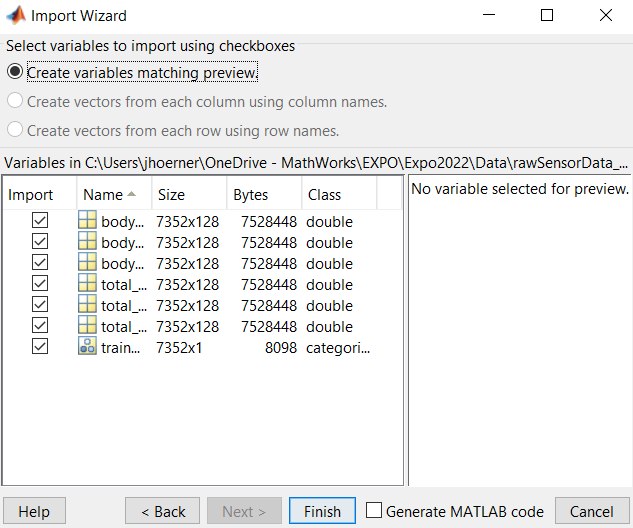

ワークスペースに 7 つの変数が表示されます。 

各行は 1 つの観測値 (128 のデータ ポイント = 128 列) を表します。「類似しているデータの行」をグループ化してクラスターを見つけます。これは、出力データ (ラベル) がない場合でも、データ セットの意味を理解するのに役立ちます。 

## データの前処理

個々のデータ ポイントが大量にあるため、アクティビティをグループ化することは困難です。このため、平均値と標準偏差を計算して、各観測のデータ ポイント数を減らします。これは次元削減として見ることができます。 

まず、 [平均](https://uk.mathworks.com/help/matlab/ref/mean.html) と [標準偏差](https://uk.mathworks.com/help/matlab/ref/std.html) を計算して、1 つの配列に入れてみましょう。 

accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% 1 つの配列に結合します
ActivityDataTrain = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% 変数をクリアします (ワークスペースをクリーンな状態に保つため)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## K-Means クラスタリング

[kmeans ドキュメントを開く](matlab: doc kmeans)

K-Means クラスタリングは、データ セットを K 個の相互に排他的なクラスターまたはグループに分割する方法です。データ内の各観測を、空間内に位置を持つオブジェクトとして扱い、各クラスター内のオブジェクトが可能な限り互いに近く、他のクラスター内のオブジェクトから可能な限り離れているパーティションを見つけます。K-Means は、すべてのクラスターにわたって、各オブジェクトからそのクラスターの重心までの距離の合計を最小化する反復アルゴリズムを使用します。 

** K-Means: **

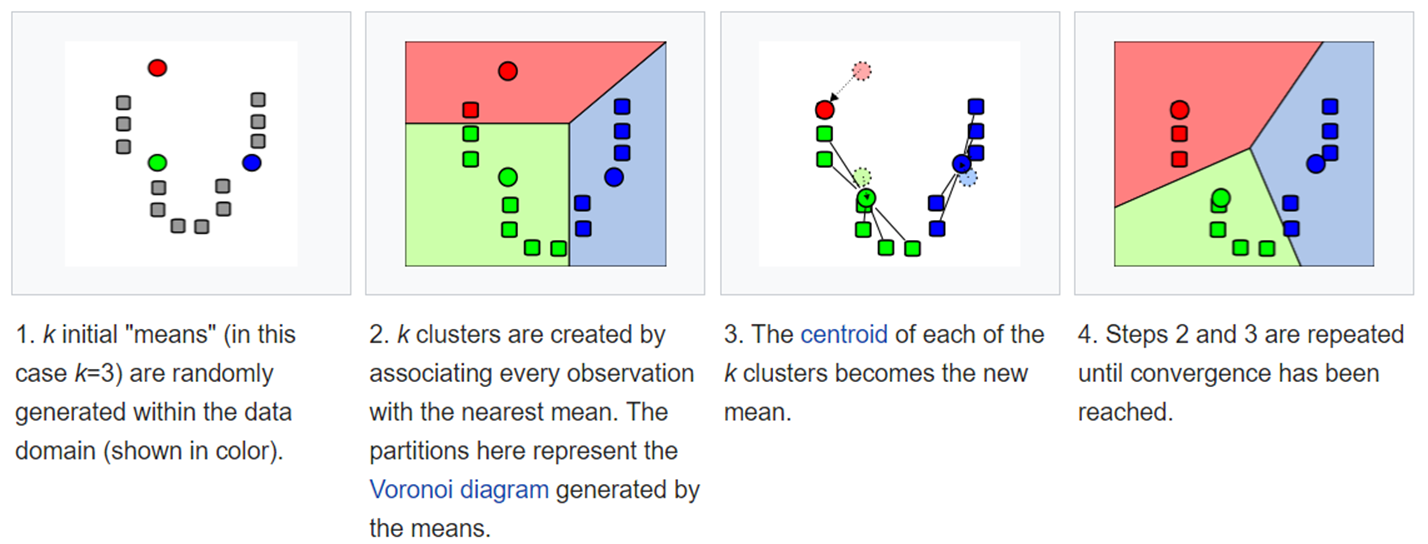

[出典: Wikipedia](https://en.wikipedia.org/wiki/K-means_clustering)

データをクラスター化するために  ***ライブ タスク***  を使用できます。これは、***ライブ エディター*** タブの ***タスク*** にあります。  ***データのクラスタリング*** を選択してください。 

入力データとして、配列 `ActivityDataTrain` を選択します。 

クラスターの数を指定できます。ラベルがないと仮定すると、実際のクラス数 (6 クラス: standing, sitting, laying, walking, walking downstairs, walking upstairs) を選択するか、より少ない数から始めてパフォーマンスを確認することもできます。 

クラスの数を試して、たとえば 2 クラス (stationary, moving) または 3 クラス (stationary, laying, moving) を選択できます。 

注: 最適なクラスター数を見つけるには、* 選択方法 * を * 最適 * に変更し、クラスター数の範囲と * 評価基準 * を指定します。 

rng('default') % ランダム シードを制御するので、クラスタリング タスクを実行するたびに同じ結果が得られます

% ライブ タスクをここに挿入します


## モデルを評価する

アクティビティの実際のラベルがわかっているので、モデルが正しかったかどうかを再確認できます。 

したがって、各クラスターのインデックスを取得し、これらのインデックスのアクティビティを表示します。 

注: このコードは 3 つのクラスターに対して機能します。クラスターの数が多い場合や少ない場合は調整する必要があります。 

idx_cl1 = clusterIndices==1;
idx_cl2 = clusterIndices==2;
idx_cl3 = clusterIndices==3;

act_1 = trainActivity(idx_cl1, :);
act_2 = trainActivity(idx_cl2, :);
act_3 = trainActivity(idx_cl3, :);
summary(act_1); %cluster 1
summary(act_2); %cluster 2
summary(act_3); %cluster 3 

ご覧のとおり、モデルはほとんどのアクティビティを正しいクラスターにグループ化しました。 

## まとめと次の手順

この例では、携帯電話から取得した測定値を同様の特性を持つグループにクラスター化しました。この手法はパターンを見つけるのに役立ちますが、データにラベルを付ける場合にも役立ちます (ラベルが利用できない場合)。 

比較的良好な結果が得られた k-means クラスタリング手法を適用しました。[こちら](https://uk.mathworks.com/help/stats/cluster-analysis.html) に記載されている他の方法を試すこともできます。 

* Copyright 2022, The MathWorks, Inc. *